% Load the train data
filename='airline_train.csv';
df = readtable(filename,'VariableNamingRule','preserve');
df

df = 103594×24 table
    Var1    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ____    ______    _____________    ___


% Delete the first columns as it is not necesarry
df = removevars(df,{'Var1'});
df

df = 103594×23 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ______    _____________    ___    ______________    ___


% Devide dependent variable and independent variable
% Picked up the first 5000 variables for computational reasons
y = df(1:5000,23)

y = 5000×1 table
    satisfaction
    ____________

         0      
         0      
         1      
         0      
         1      
         0      
         0      
         1      
         0      
         0      
         0      
         0      
         0      
         1      
         0      
         0      


X = df(1:5000,1:20)

X = 5000×20 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness
    ______    _____________    ___    ______________    _____    _______________    _____________________    ___________________________

|=======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | Names        |              |
|=======================================================================================|
|    1 | Best   |      0.3846 |      11.123 |      0.3846 |       kernel |       1638.8 |
|    2 | Best   |      0.1358 |     0.21674 |      0.1358 |       normal |            - |
|    3 | Accept |      0.1358 |     0.19554 |      0.1358 |       normal |            - |
|    4 | Accept |      0.3466 |      10.001 |      0.1358 |       kernel |       546.34 |
|    5 | Accept |      0.1358 |     0.12571 |      0.1358 |       normal |            - |
|    6 | Accept |      0.1358 |     0.11095 |      0.1358 |       normal |            - |
|    7 | Accept |      0.4354 |      10.386 |      0.1358 |       kernel |         4916 |
|    8 | A

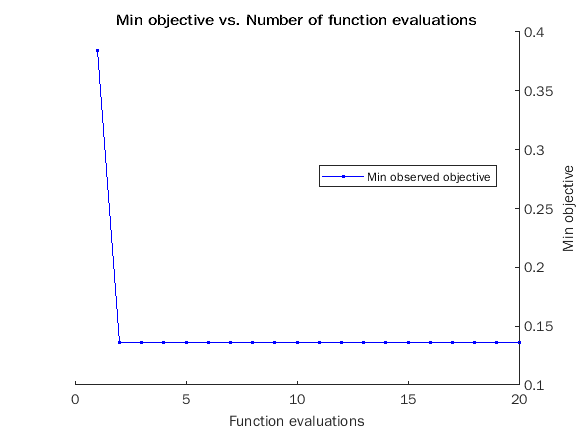


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 20 reached.
Total function evaluations: 20
Total elapsed time: 113.9004 seconds
Total objective function evaluation time: 104.2786

Best observed feasible point:
    DistributionNames    Width
    _________________    _____

         normal           NaN 

Observed objective function value = 0.1358
Function evaluation time = 0.21674




rng(2021); % For reproducibility
Mdl_HP_NB = fitcnb(X,y,'OptimizeHyperparameters',{'DistributionNames','Width'}, ...
    'HyperparameterOptimizationOptions', ...
    struct('Optimizer','gridsearch','KFold',10,'MaxObjectiveEvaluations',20));


% Save the model
save('Naive_Bayes_HP_tuning','Mdl_HP_NB');